clear
close all


Part a

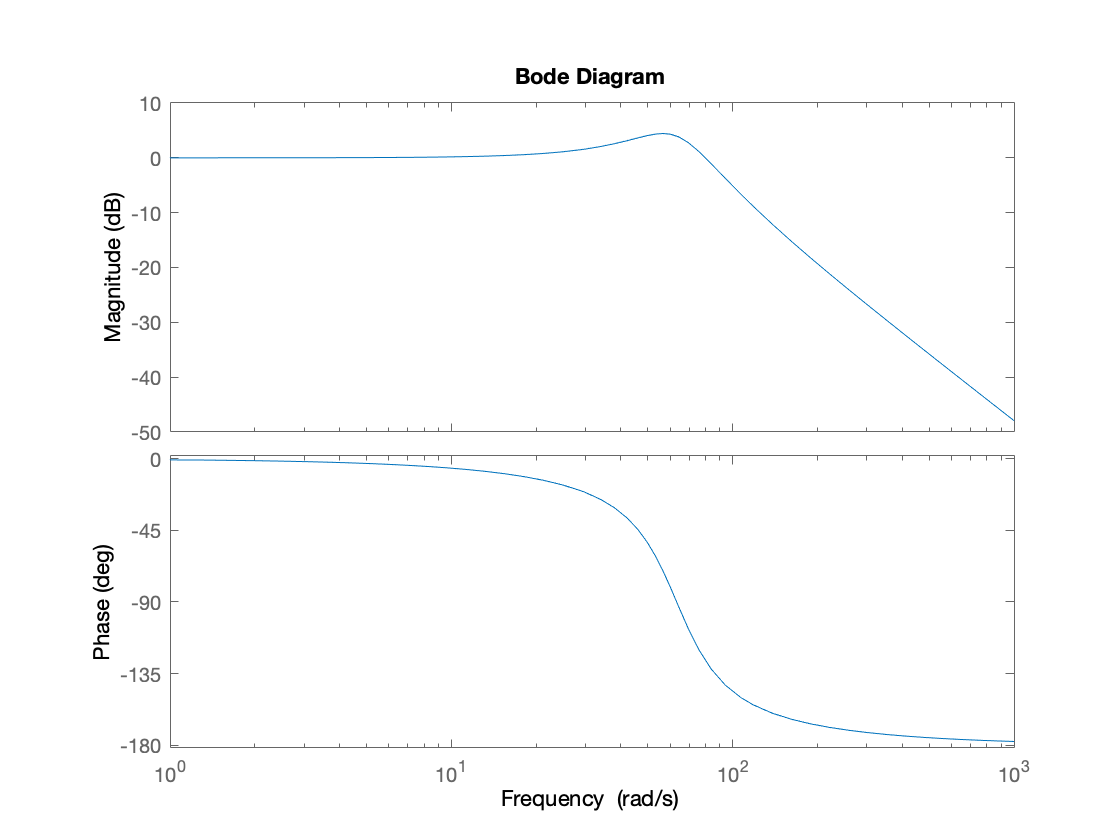


R = 100;
C = 10e-5;
L = 2.5;

s = tf('s');

T2 = 1/(L*C*s^2 + R*C*s + 1);

bode(T2)

Part b

Ts = 1e-4;
ws = 20;
[mag, phase] = bode(T2, ws)

mag = 1.0847

phase = -12.5288

Part c


out = sim("Exercise4_sim.slx")

out =   Simulink.SimulationOutput:

                   tout: [10001x1 double] 
                      u: [10001x1 double] 
                      w: [10001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


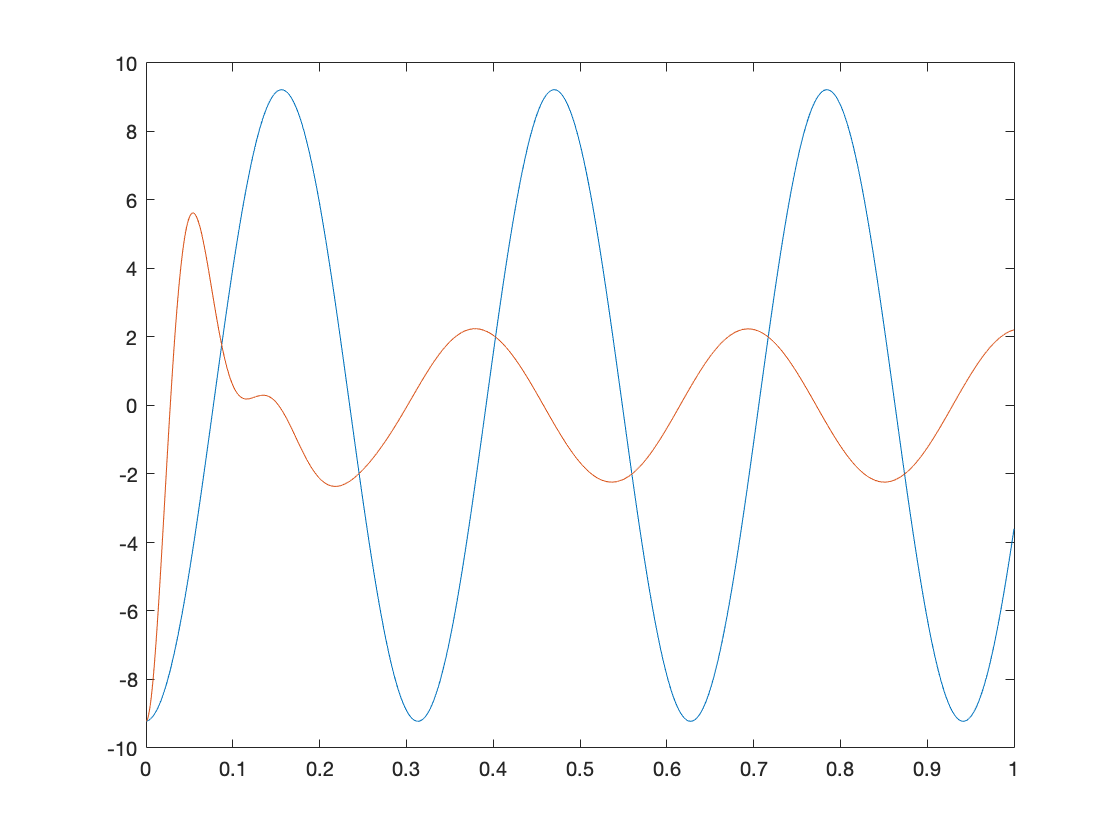


t = out.tout;
u = out.u;
w = out.w;

plot(t, u, t, w)

Part d

out =   Simulink.SimulationOutput:

                   tout: [10001x1 double] 
                      u: [10001x1 double] 
                      w: [10001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


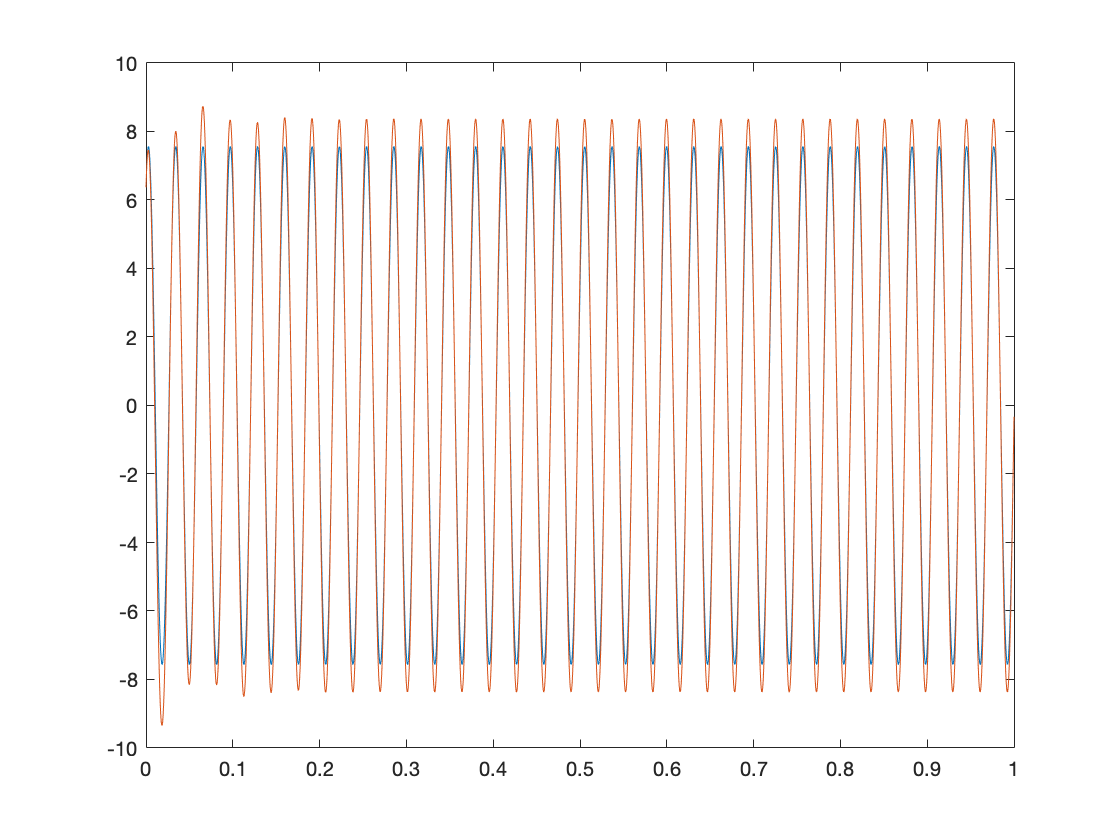

out =   Simulink.SimulationOutput:

                   tout: [10001x1 double] 
                      u: [10001x1 double] 
                      w: [10001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


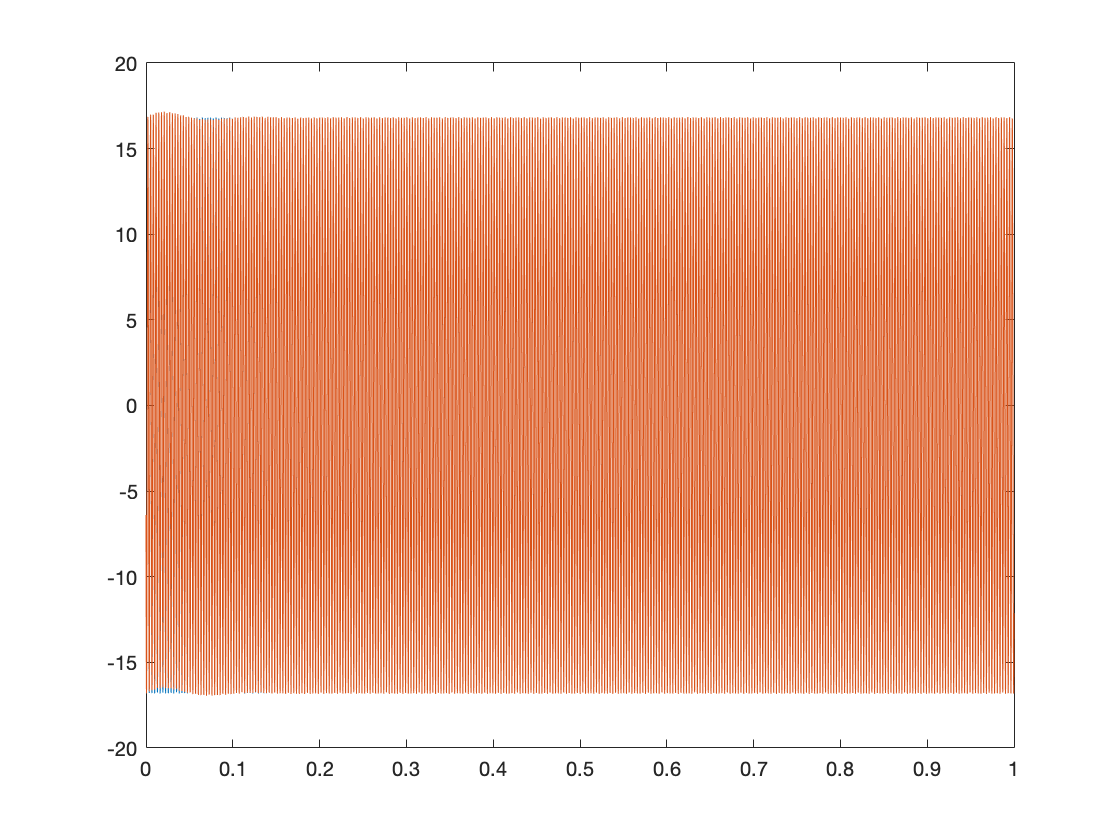

for ws = [200 2000]
    out = sim("Exercise4_sim.slx")
    t = out.tout;
    u = out.u;
    w = out.w;
    
    figure
    plot(t, u, t, w)
end